# Plotting

One of the most important uses of MATLAB is the ability to visualize your data. When plotting in MATLAB, there are few nuances that we have to pay close attention to. By the end of this notebook, you will be able to

- Plot two vectors of the same length against each other

- Add features such as titles, colors, and legends to your graph

- Create a histogram and a scatter plot of pre-loaded data. 

## The `plot` function

Recall that when we typically sketch the graph of a function, the domain is plotted on the $x$-axis and the range is plotted on the $y$-axis:

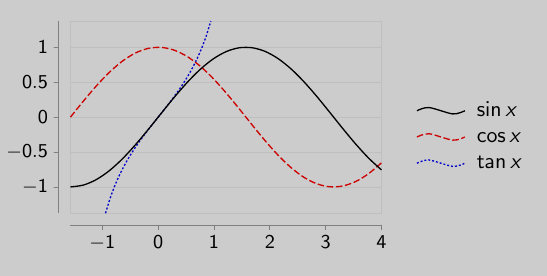

If you just want to graph a function in MATLAB, the first thing you'll need to do is create a vector containing the $x$-values that will be input into our function. This is typically done using `linspace:`

%% Create a vector of x-values

x = linspace(-10,10,1000);

Now we can define the function that we wish to plot and use the `plot` command to generate a figure:

%% Plot y = x^2
y = x.^2;
plot(x,y)

hold off

(Notice we used `.^ `to indicate that we wanted to square each entry in `x `as opposed to multiply `x` by itself.). 

You try: Plot the function $f(x) = \sin(x)$ on the interval from $0$ to $2\pi$. Store your $x$ and $y$ values in vectors called `x1` and `y1` respectively. 

%% Code here.

x1 = linspace(0, 2*pi, 1000)
y1 = sin(x1)

plot(x1,y1)


We can add multiple graphs to a single plot using the `hold on` feature:

hold on % tells MATLAB not to create a new plot
y2 = cos(x1);
plot(x1,y2)
hold off % always enter this when you are done plotting. 

## Getting Fancy

Most likely, you will want to present your data in a visually-appealing manner. Plots should also be understandable by the general public, so you will want to add things like titles, colors, and legends. 

You may wish to change up the style and color of the curves on your plots. For this, `plot` can accept a third argument that allows you to specify color, line style, and marker style. For example, the command

`plot(x,y,'r--o')`

produces a plot of `y` against `x `using a red (`r)`, dashed (`--)`, line with circle (`o`) markers. 

%% Run this code to generate a fancy plot

x = linspace(1,10,10);
y = 2*x-1;
plot(x,y,'r--o')

hold off


For a full list of the style characters you can use visit: [https://www.mathworks.com/help/matlab/ref/linespec.html](https://www.mathworks.com/help/matlab/ref/linespec.html).You'll also see in LineSpec documentation that you can specify a line width. 

You try: Create a plot containing the graphs of $y=2x^2-1$ and $y = \sqrt{x}$. Play around with different colors, styles, and line widths. 

%% Code here.







Another important feature to add to a graph is a title and axis labels. You can do this using the commands `title("your_title")`, `ylabel("your_y_label")`, and `xlabel("your_x_label"). `

If you are plotting multiple curves, you can create a legend using `legend("first", "second", ...).` Just make sure the order you use matches the order you've plotted your cruves. 

Finally, you can set axis limits using `xlim([lower_limit upper_limit]) `and `ylim([lower_limit upper_limit]).`

You can include these calls after using the `plot` command:

%% A complete graph

x = linspace(-2*pi, 2*pi, 1000);
y1 = sin(x);
y2 = cos(x);
y3 = tan(x);
plot(x,y1, 'r--')
hold on
plot(x,y2,'k')
plot(x, y3, 'b:')
hold off
title("sin(x) vs. cos(x) vs. tan(x)")

xlabel('x-values')
ylabel('f(x) values')

legend("y = sin(x)", "y = cos(x)", "y=tan(x)") % keep track of order!

% We can also set axis limits. 
xlim([-1 1.5]) 
ylim([-1 1])


You try: Revist your plot of $y = 2x^2-1$ with $y = \sqrt{x$. Add a title, legend, and $x$ and $y$ labels. 

%% Code here.












## Histograms and Scatter Plots

There are many other types of plots that can be created using MATLAB, but in this notebook we will just look at scatter plots and histograms. Recall that if you come across another type of plot, Google is your friend!

%% Creating a histogram of random values.

X = randi(10, 1, 10) %just creating some random data

X =      6    10     1     5     2    10     1     8     9     9


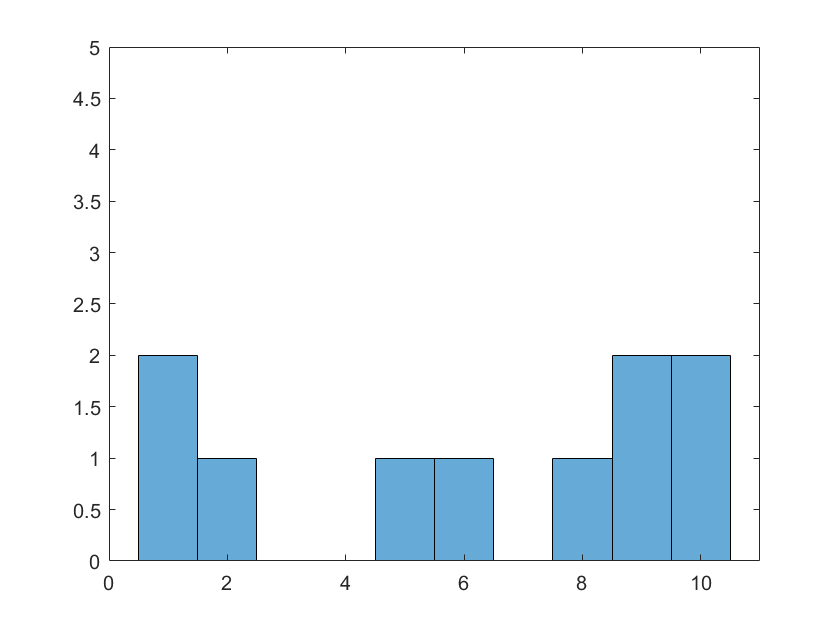

histogram(X)
xlim([0 11])
ylim([0 5])

We can also create a a scatterplot using a similar call.

%% Creating a scatterplot of random values
Y = 2*X+2*rand(1,10) - 1 % just creating some random data

Y =    11.1689   19.7996    1.5197   10.6001    3.8628   20.8213    1.3637   15.5276   17.2911   17.2721


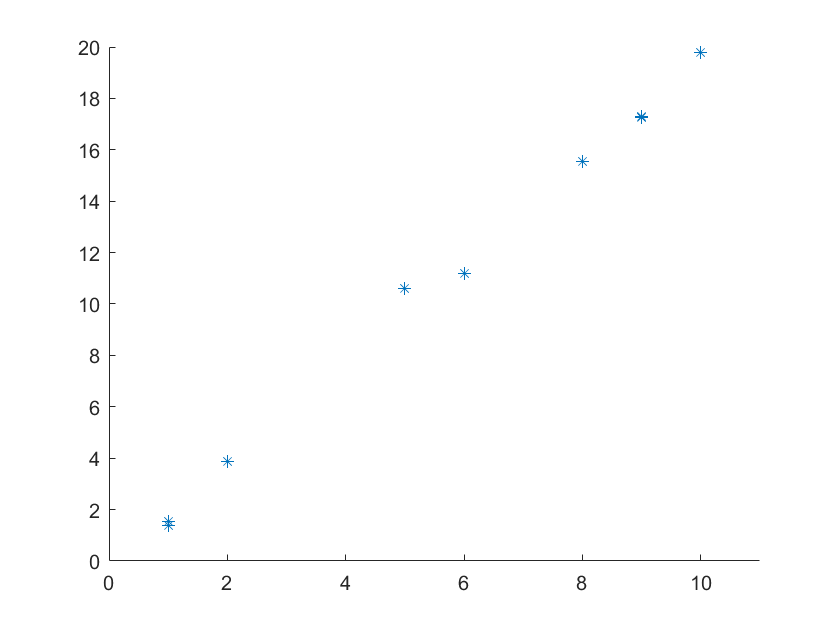

scatter(X,Y,'*')
xlim([0 11])
ylim([0 20])

Now let's graph the number of award nominations Beyonce has received each year since 2003. 

This first code block just loads the data set you will need. 

%% Import Beyonce data set.

load beyonce.mat


In the code block below, create a histogram using the variable `total_noms. `Upgrade your plot by adding a title and playing with different colors. Remember you can always get hints by typing `doc histogram `to explore the available options. 

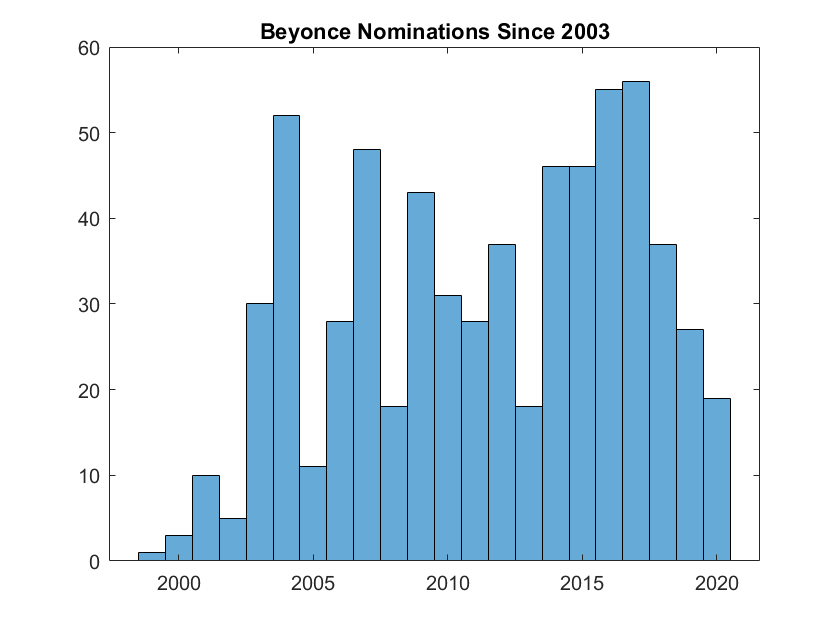

%% Code here.

histogram(total_noms)
title("Beyonce Nominations Since 2003")

In the code block below, create a scatter plot of `number_noms `against `nom_years. `Again, personalize your plot by adding a title and playing with different colors. Remember you can always get hints by typing `doc scatter `to explore the available options. 

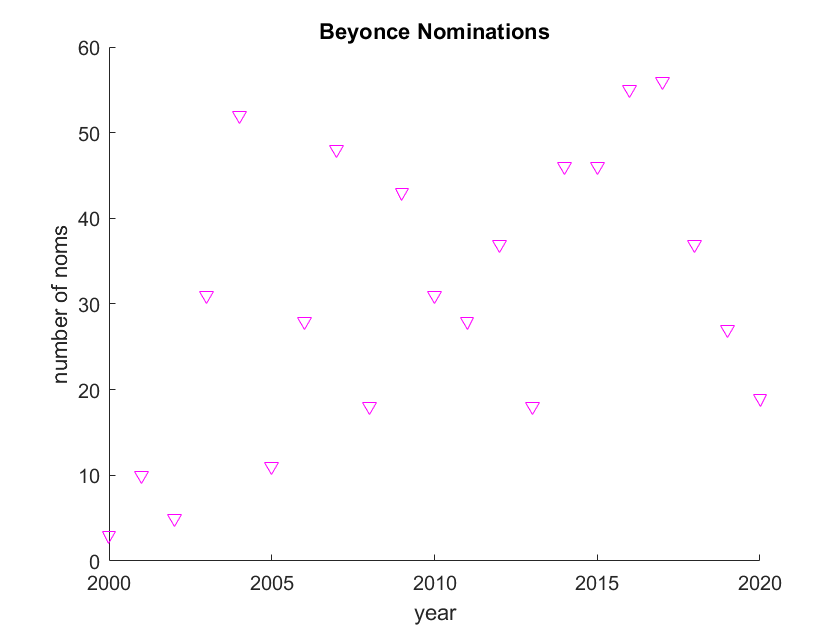

%% Code here.

scatter(nom_years, number_noms, 'mv')
title("Beyonce Nominations")
xlabel("year")
ylabel("number of noms")

If you'd like to save your plots, visit [https://www.mathworks.com/help/matlab/ref/saveas.html](https://www.mathworks.com/help/matlab/ref/saveas.html) to learn about the different ways to do this. 

That's it for this notebook! Note that there are tons of other plots and visualizations you can create using MATLAB, and this is just an introduction. You can even create 3D plots. If you are interested in learning about those, just peruse the documentation. 

## Disclaimers and References

*This notebook was written for the *[*The EDGE Program*](https://www.edgeforwomen.org/)* by Anila Yadavalli, Ph. D., 2021.*

*Redistribution of the material contained in this repository is conditional on acknowledgement of Anila Yadavalli, Ph.D.'s original authorship. *

*The Beyonce Data Set used in this notebook is a cleaned and modified version of the *[Storytelling with Data - The Beyonce Edition](https://dataverse.tdl.org/dataset.xhtml?persistentId=doi:10.18738/T8/XL8NIX) from The Texas Data Repository.